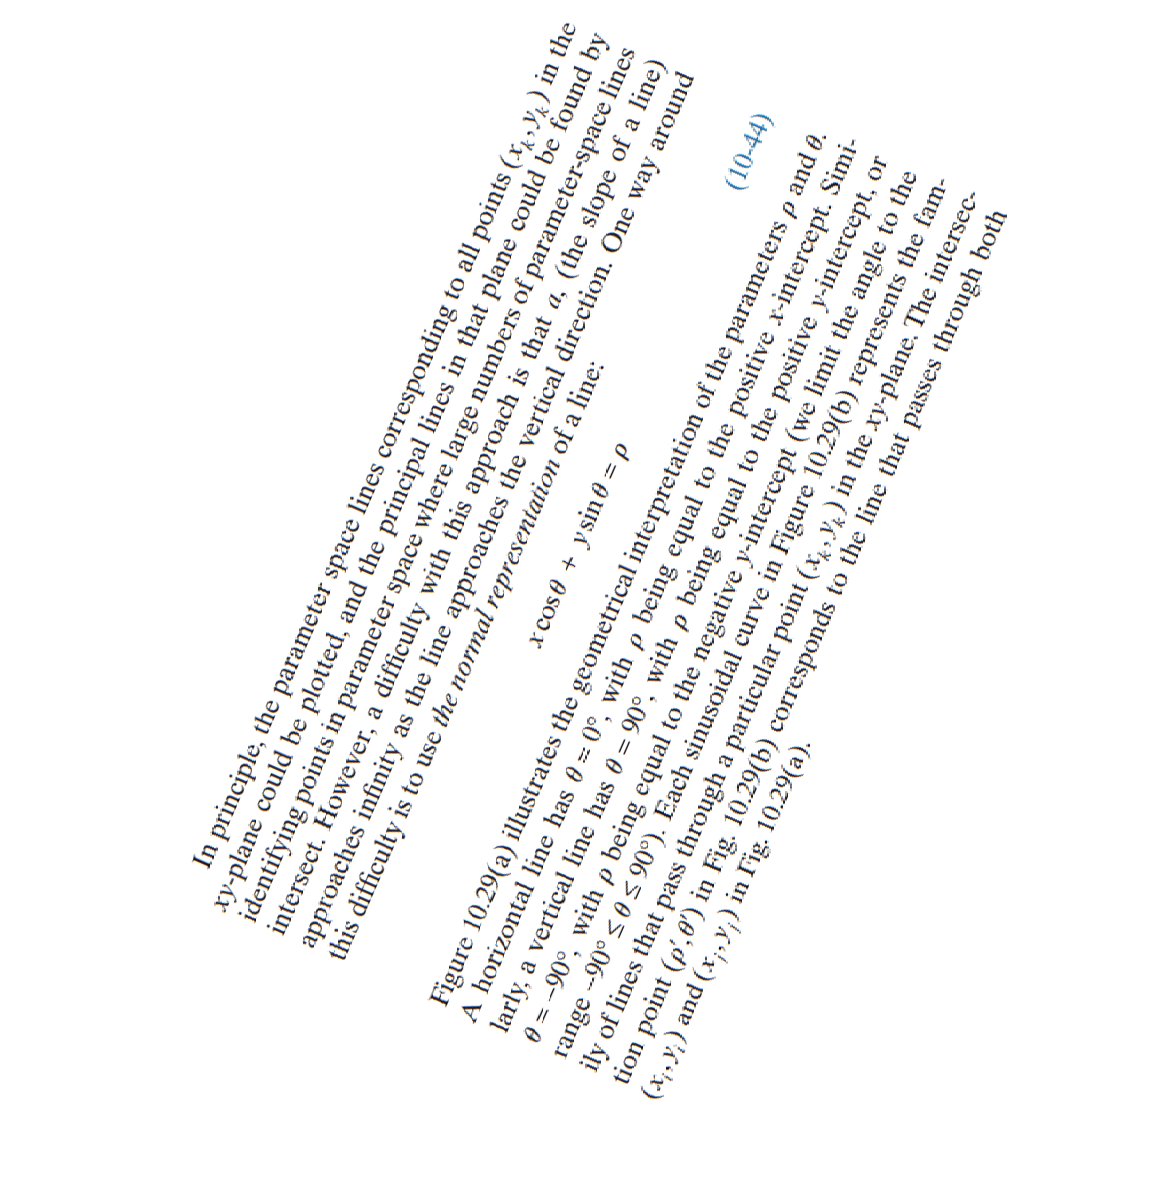

clf;clear;
image = imread("../images/tilted.PNG");
imshow(image, []);

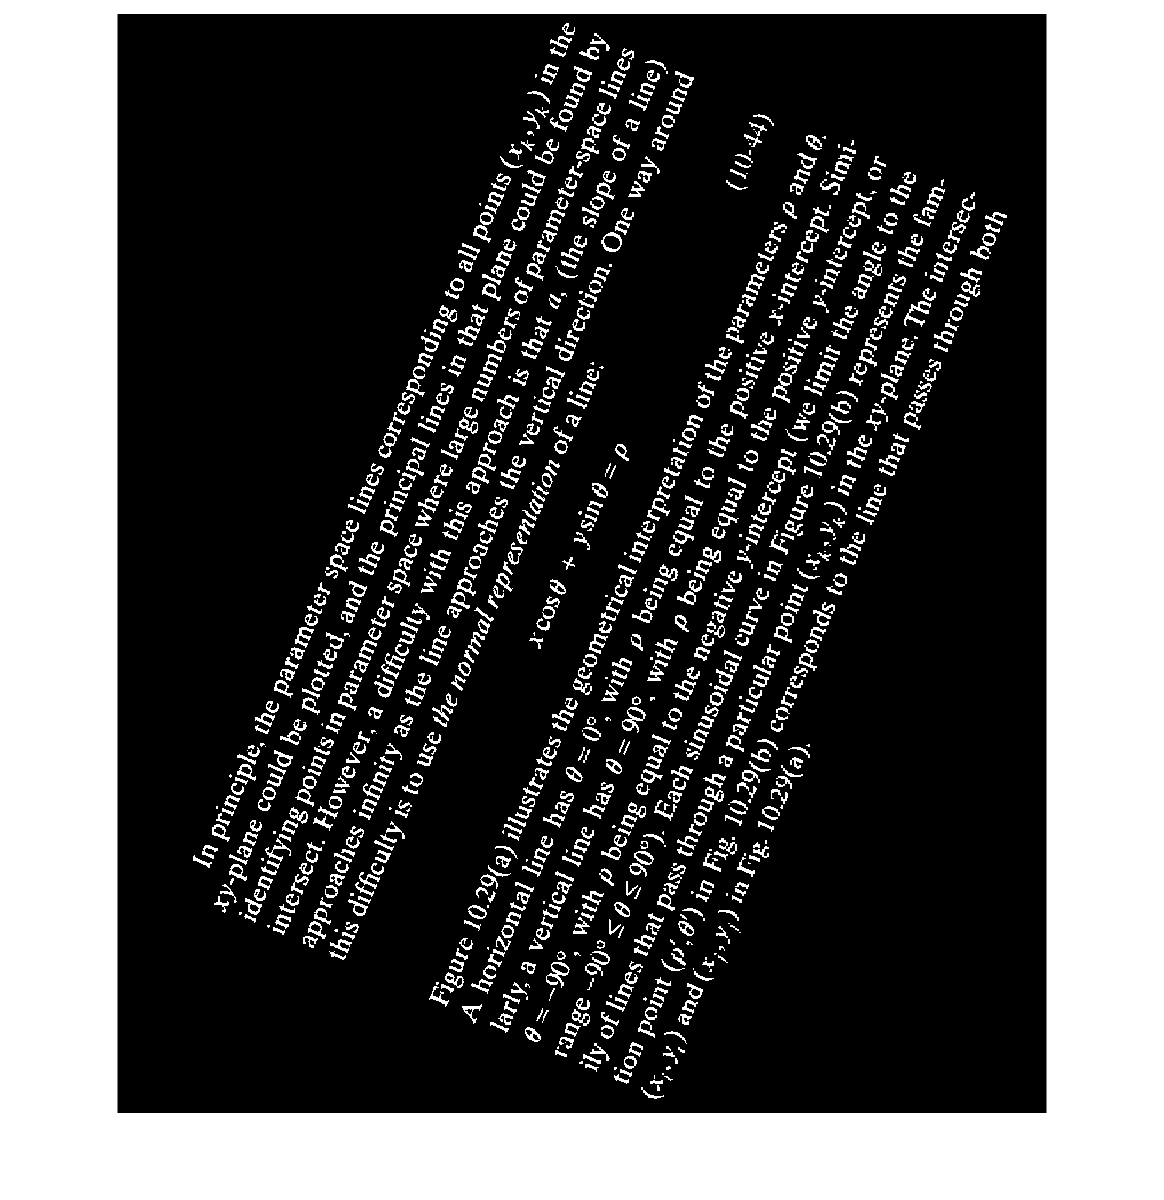

img = rgb2gray(image);
[M, N] = size(img);
img = ~imbinarize(img, 0.7);
imshow(img, [])

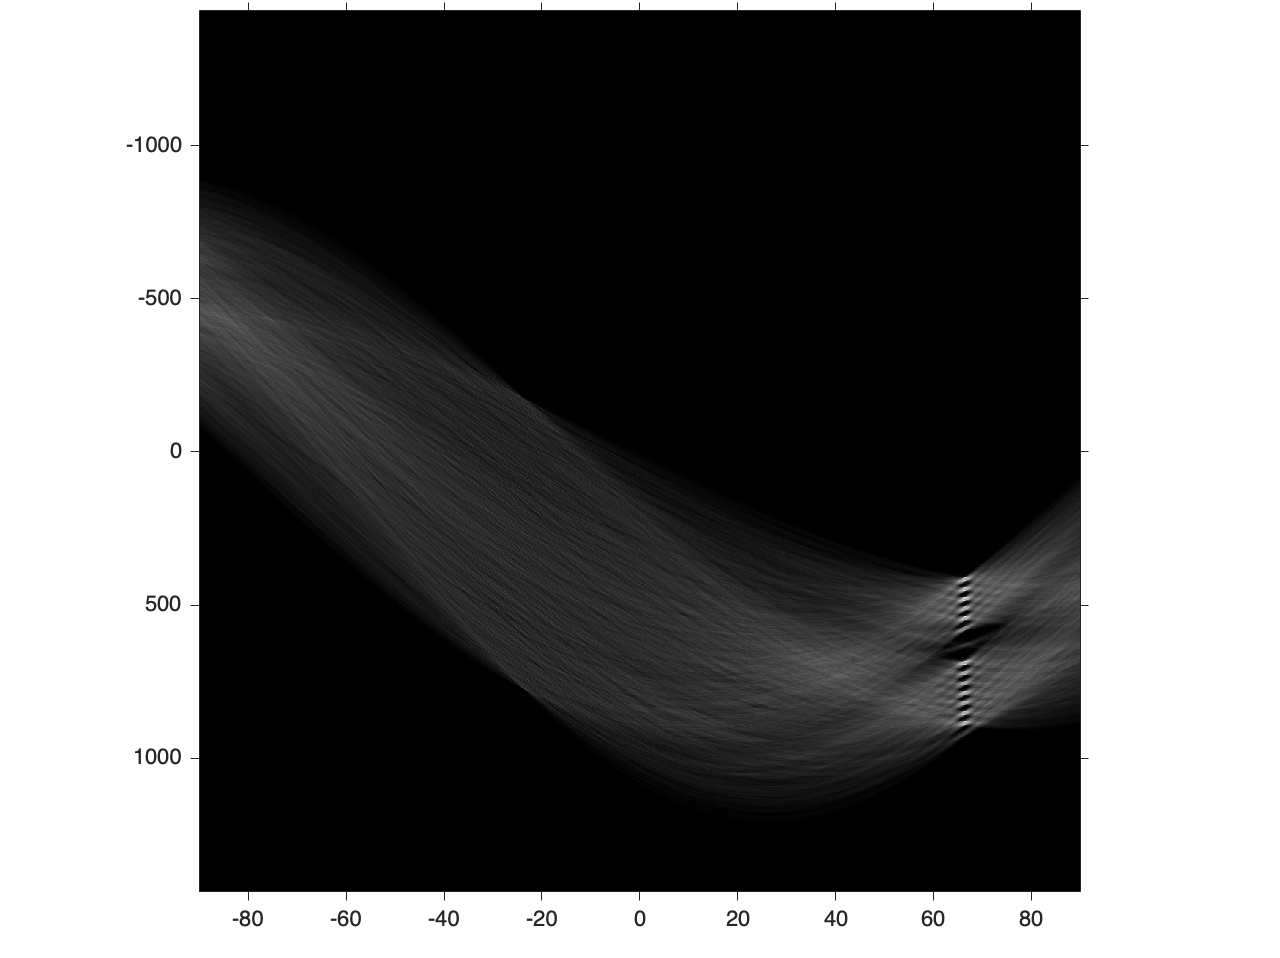

delta_theta = 0.125;
delta_rho = 2.5;
theta = -90:delta_theta:(90-delta_theta);
D = round(sqrt(M^2+N^2));
rho = -D:delta_rho:(D-delta_rho);
cosine = cosd(theta);
sine = sind(theta);
accumulator = zeros([length(rho), length(theta)]);
for x=0:(M-1)
    for y=0:(N-1)
        if img(x+1, y+1)
            r = x * cosine + y * sine;
            r = round((r+D+1) / (2*D+1) * length(rho));
            for i=1:length(theta)
                accumulator(r(i), i) = accumulator(r(i), i) + 1;
            end
        end
    end
end
imshow(accumulator, [], 'XData', theta, 'YData', rho)
axis on; axis square;

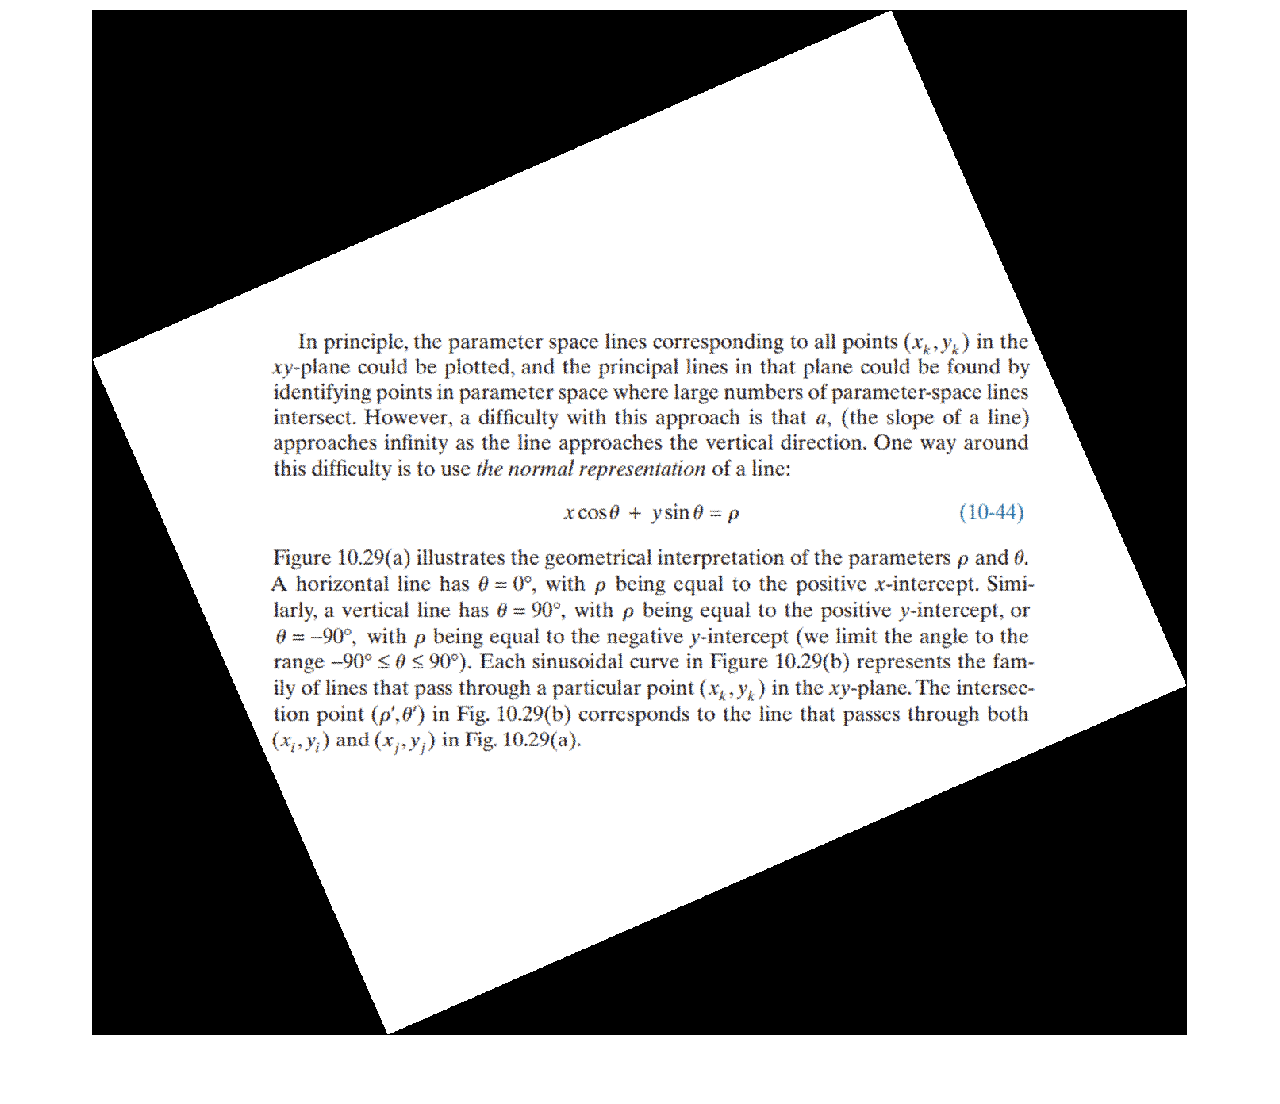

[r, c] = find(accumulator == max(accumulator(:)));
theta = theta(c);
image = imrotate(image, -theta);
imshow(image, [])